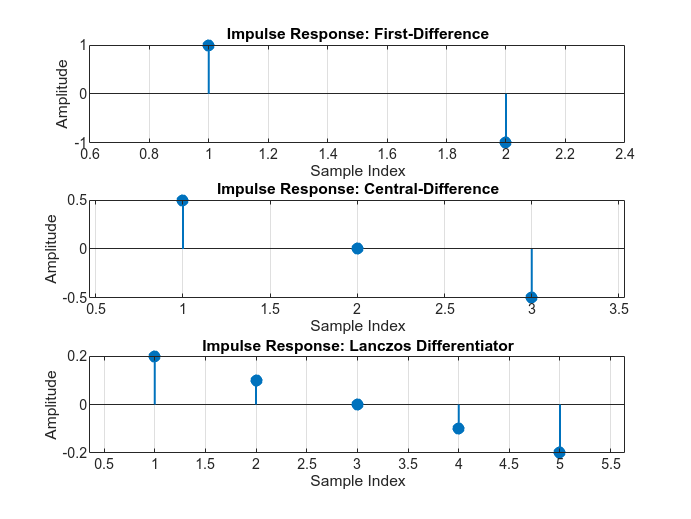

% ========================================================================
% Part 1: Simple Differentiators
% ========================================================================
% Implements:
%   (a) First-Difference Differentiator
%   (b) Central-Difference Differentiator
%   (c) Lanczos Differentiator
% Tasks:
%   1. Plot impulse responses
%   2. Plot frequency responses (-pi..pi) with y-axis from 0..pi
%   3. Pass a clean sinusoid through each
%   4. Apply each to a noisy sinusoidal signal
%
% Discussion questions are omitted.
% ========================================================================

clear; close all; clc;

%% 1) Define the Differentiators
% ------------------------------------------------------------------------
% First-Difference: y_FD(n) = x(n) - x(n-1)
b_fd = [1, -1];

% Central-Difference: y_CD(n) = [x(n) - x(n-2)] / 2
b_cd = [0.5, 0, -0.5];

% Lanczos-based (given): hL(k) = [0.2, 0.1, 0, -0.1, -0.2]
b_lanczos = [0.2, 0.1, 0, -0.1, -0.2];

%% 2) Plot Impulse Responses
% ------------------------------------------------------------------------
figure('Name','Impulse Responses','NumberTitle','off');

subplot(3,1,1);
stem(b_fd,'filled','LineWidth',1.2); grid on;
title('Impulse Response: First-Difference');
xlabel('Sample Index'); ylabel('Amplitude');

subplot(3,1,2);
stem(b_cd,'filled','LineWidth',1.2); grid on;
title('Impulse Response: Central-Difference');
xlabel('Sample Index'); ylabel('Amplitude');

subplot(3,1,3);
stem(b_lanczos,'filled','LineWidth',1.2); grid on;
title('Impulse Response: Lanczos Differentiator');
xlabel('Sample Index'); ylabel('Amplitude');

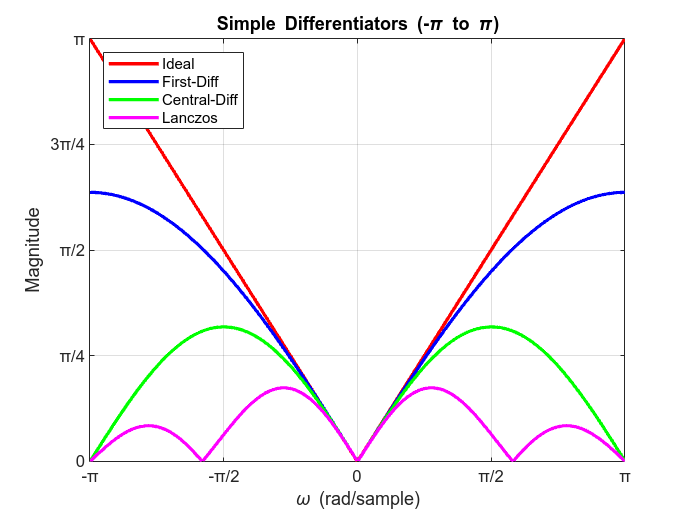


%% 3) Frequency Response from -pi to pi (Magnitude)
% ------------------------------------------------------------------------
% We do a custom FFT-based approach to plot from -pi..pi (instead of freqz default 0..pi)
N = 1024;  % FFT length for a smooth plot

% Compute DFTs and shift them for -pi..pi
B_fd       = fftshift(fft(b_fd, N));
B_cd       = fftshift(fft(b_cd, N));
B_lanczos  = fftshift(fft(b_lanczos, N));

% Frequency axis from -pi to pi
w = linspace(-pi, pi, N);

% Magnitude responses
Mag_fd       = abs(B_fd);
Mag_cd       = abs(B_cd);
Mag_lanczos  = abs(B_lanczos);

% Ideal Differentiator: |H_ideal(w)| = |w|
Mag_ideal = abs(w);

% Plot all four
figure('Name','Frequency Responses','NumberTitle','off');
plot(w, Mag_ideal, 'r', 'LineWidth',2); hold on;
plot(w, Mag_fd,    'b', 'LineWidth',2);
plot(w, Mag_cd,    'g', 'LineWidth',2);
plot(w, Mag_lanczos, 'm','LineWidth',2);
grid on; xlabel('\omega (rad/sample)'); ylabel('Magnitude');
title('Simple Differentiators (-\pi to \pi)');

% Adjust axes to match the reference figure style
xlim([-pi pi]);
ylim([0 pi]);  % so the ideal line goes up to pi at w = ±pi

% Set ticks at multiples of pi
xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-π','-π/2','0','π/2','π'});
yticks([0 pi/4 pi/2 3*pi/4 pi]);
yticklabels({'0','π/4','π/2','3π/4','π'});

legend('Ideal','First-Diff','Central-Diff','Lanczos','Location','NorthWest');

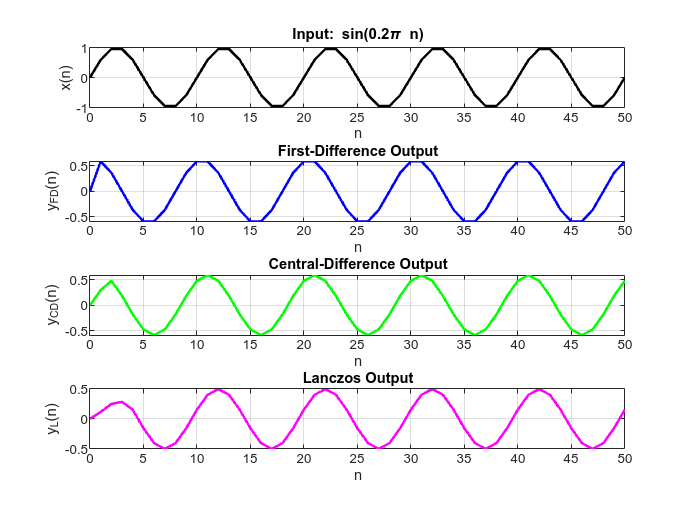


%% 4) Pass a Clean Sinusoid Through Each Differentiator
% ------------------------------------------------------------------------
n = 0:50;                % sample indices
x_clean = sin(0.2*pi*n); % test sinusoid

y_fd_clean      = filter(b_fd, 1, x_clean);
y_cd_clean      = filter(b_cd, 1, x_clean);
y_lanczos_clean = filter(b_lanczos, 1, x_clean);

figure('Name','Clean Sinusoid Through Differentiators','NumberTitle','off');
subplot(4,1,1);
plot(n, x_clean, 'k','LineWidth',1.5); grid on;
title('Input: sin(0.2\pi n)');
xlabel('n'); ylabel('x(n)');

subplot(4,1,2);
plot(n, y_fd_clean, 'b','LineWidth',1.5); grid on;
title('First-Difference Output');
xlabel('n'); ylabel('y_{FD}(n)');

subplot(4,1,3);
plot(n, y_cd_clean, 'g','LineWidth',1.5); grid on;
title('Central-Difference Output');
xlabel('n'); ylabel('y_{CD}(n)');

subplot(4,1,4);
plot(n, y_lanczos_clean, 'm','LineWidth',1.5); grid on;
title('Lanczos Output');
xlabel('n'); ylabel('y_{L}(n)');

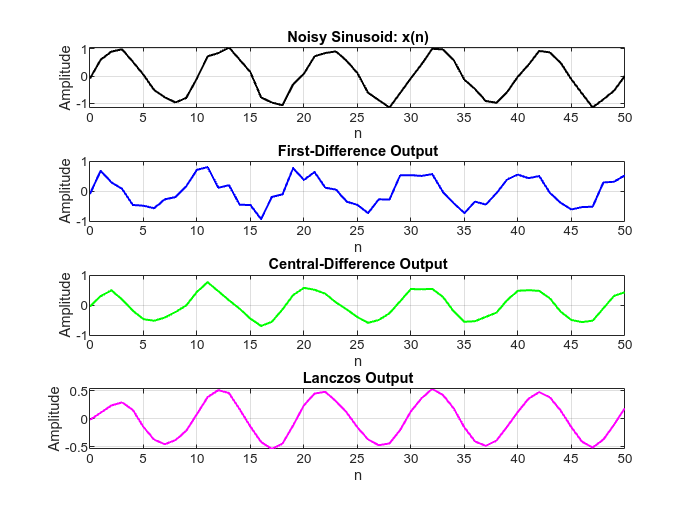


%% 5) Practical Application: Noisy Sinusoidal Signal
% ------------------------------------------------------------------------
% x_noisy(n) = sin(0.2*pi*n) + 0.1 * randn(...)
x_noisy = sin(0.2*pi*n) + 0.1*randn(size(n));

% Apply each differentiator
y_fd_noisy      = filter(b_fd, 1, x_noisy);
y_cd_noisy      = filter(b_cd, 1, x_noisy);
y_lanczos_noisy = filter(b_lanczos, 1, x_noisy);

figure('Name','Noisy Sinusoid Through Differentiators','NumberTitle','off');
subplot(4,1,1);
plot(n, x_noisy, 'k','LineWidth',1.2); grid on;
title('Noisy Sinusoid: x(n)');
xlabel('n'); ylabel('Amplitude');

subplot(4,1,2);
plot(n, y_fd_noisy, 'b','LineWidth',1.2); grid on;
title('First-Difference Output');
xlabel('n'); ylabel('Amplitude');

subplot(4,1,3);
plot(n, y_cd_noisy, 'g','LineWidth',1.2); grid on;
title('Central-Difference Output');
xlabel('n'); ylabel('Amplitude');

subplot(4,1,4);
plot(n, y_lanczos_noisy, 'm','LineWidth',1.2); grid on;
title('Lanczos Output');
xlabel('n'); ylabel('Amplitude');


% End of Part 1
